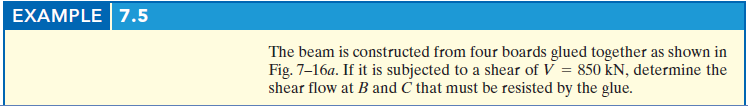

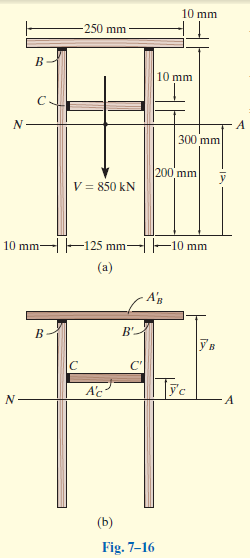

# symbolic units class

u = symunit;

# section properties

yc = [300/2 300/2 200+10/2 300+10/2]*u.mm;
Ac = [10*300 10*300 125*10 250*10]*u.mm^2;
Ic = [10*300^3 10*300^3 125*10^3 250*10^3]/sym(12)*u.mm^4;
[yn Qn In] = beam.neutral_axis(yc, Ac, Ic); %#ok
I = sum(In);

# shear flow

V = 850*u.kN;
q = rewrite(V*Qn/I, u.kN/u.m).'/2;
q_vpa = vpa(q) %#ok

$$q\_vpa = \left(\begin{array}{c} -681.67461618038835129221557982624\,\frac{\mathrm{kN}}{m}\\ -681.67461618038835129221557982624\,\frac{\mathrm{kN}}{m}\\ 49.802711684411934340983786653972\,\frac{\mathrm{kN}}{m}\\ 1313.5465206763647682434473729985\,\frac{\mathrm{kN}}{m} \end{array}\right)$$

clear q_vpa;